# AD2 Testing

## Clear Workspace

close all; clearvars; clc;

## Set System Variables

outputRate = 1e6; % Sets the rate that the NI-Board output at
bufferForPreLoad = 500e3; % sets the length of buffer for preloading
pkpV = 1; % pk-pk voltage per frequency
f1 = 10e3; % lowest frequency component Hz
f2 = 30e3; % mid frequency component Hz
f3 = 50e3; % highest frequency component Hz

## Setup Device

dq = daq("digilent");% create data acquisition object
addoutput(dq, "AD2_0", "ao0" ,'Voltage'); %add an output channel
dq.Rate = outputRate;

## Create Output Vector

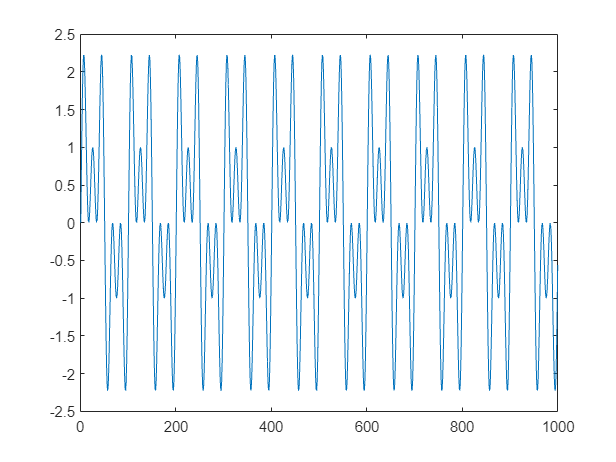

output = createSine(pkpV, f1, f2, f3, outputRate, "bipolar", bufferForPreLoad);
plot(output)
xlim([0 1e3])

preload(dq, output)

## Output on Device

figure
ButtonHandle = uicontrol('Style', 'PushButton', ...
                         'String', 'Stop loop', ...
                         'Callback', 'delete(gcbf)');


start(dq, "continuous")
while true
    if ~ishandle(ButtonHandle)
        disp('Loop stopped by user');
        break;
    end
end

stop(dq)

## Sine Function

function sine = createSine(A, frq1, frq2, frq3, sampleRate, type, bufferForPreLoad)
    timeStep = 1/sampleRate; % period of the sampling frequency
    periods = 1/eval(gcd(sym([frq1 frq2 frq3]))); % calculates the length of the period for a periodic
    t = (0:timeStep:periods-timeStep)'; % calculates the time vector from the period
        if type == "bipolar"
            y = A*sin(2*pi*frq1*t) + A*sin(2*pi*frq2*t) + A*sin(2*pi*frq3*t); % calculates the signal along the time vector
        elseif type == "unipolar"
            y = A*sin(2*pi*frq1*t) + A*sin(2*pi*frq2*t) + A*sin(2*pi*frq3*t) + A; % calculates the signal along the time vector
        end
    numCycles = ceil(bufferForPreLoad/(periods/timeStep)); % calculate the number of cycles to make a full buffer for preloading
    sine = repmat(y, numCycles, 1); % extends the data vector to match or execed the buffer length
end